# Vorbereitung für das Morphen Erstellen und Bearbeiten der Referenzpunkte

Die Abschnitte dieses Skripts sollen dabei helfen, die Referenzpunkte für das Morphing zu erstellen. Dieser Abschnitt sollte zu Beginn ausgeführt werden um den workspace vorzubereiten. Die weiteren Abschnitte sind:

**"Punkte erstellen"**: Erstellen der Referenzpunkte (auch auch als Referenzpunkte bekannt) für Anfangs- und Zielbild mit dem in MATLAB® integrierten Control Point Selection Tool.

**"Punkte speichern"**: Speichert die erstellten Punkte als .mat-Dateien.

**"Bestehende Punkte Bearbeiten"**: Hiermit sind das weitere Hinzufügen von Punkten oder Korrekturen möglich.

**"Punkte laden"**: Bei Bedarf

% Vor Beginn ausführen
close all
clear
clc
addpath('./img_in/')
addpath('./points')

## Punkte erstellen

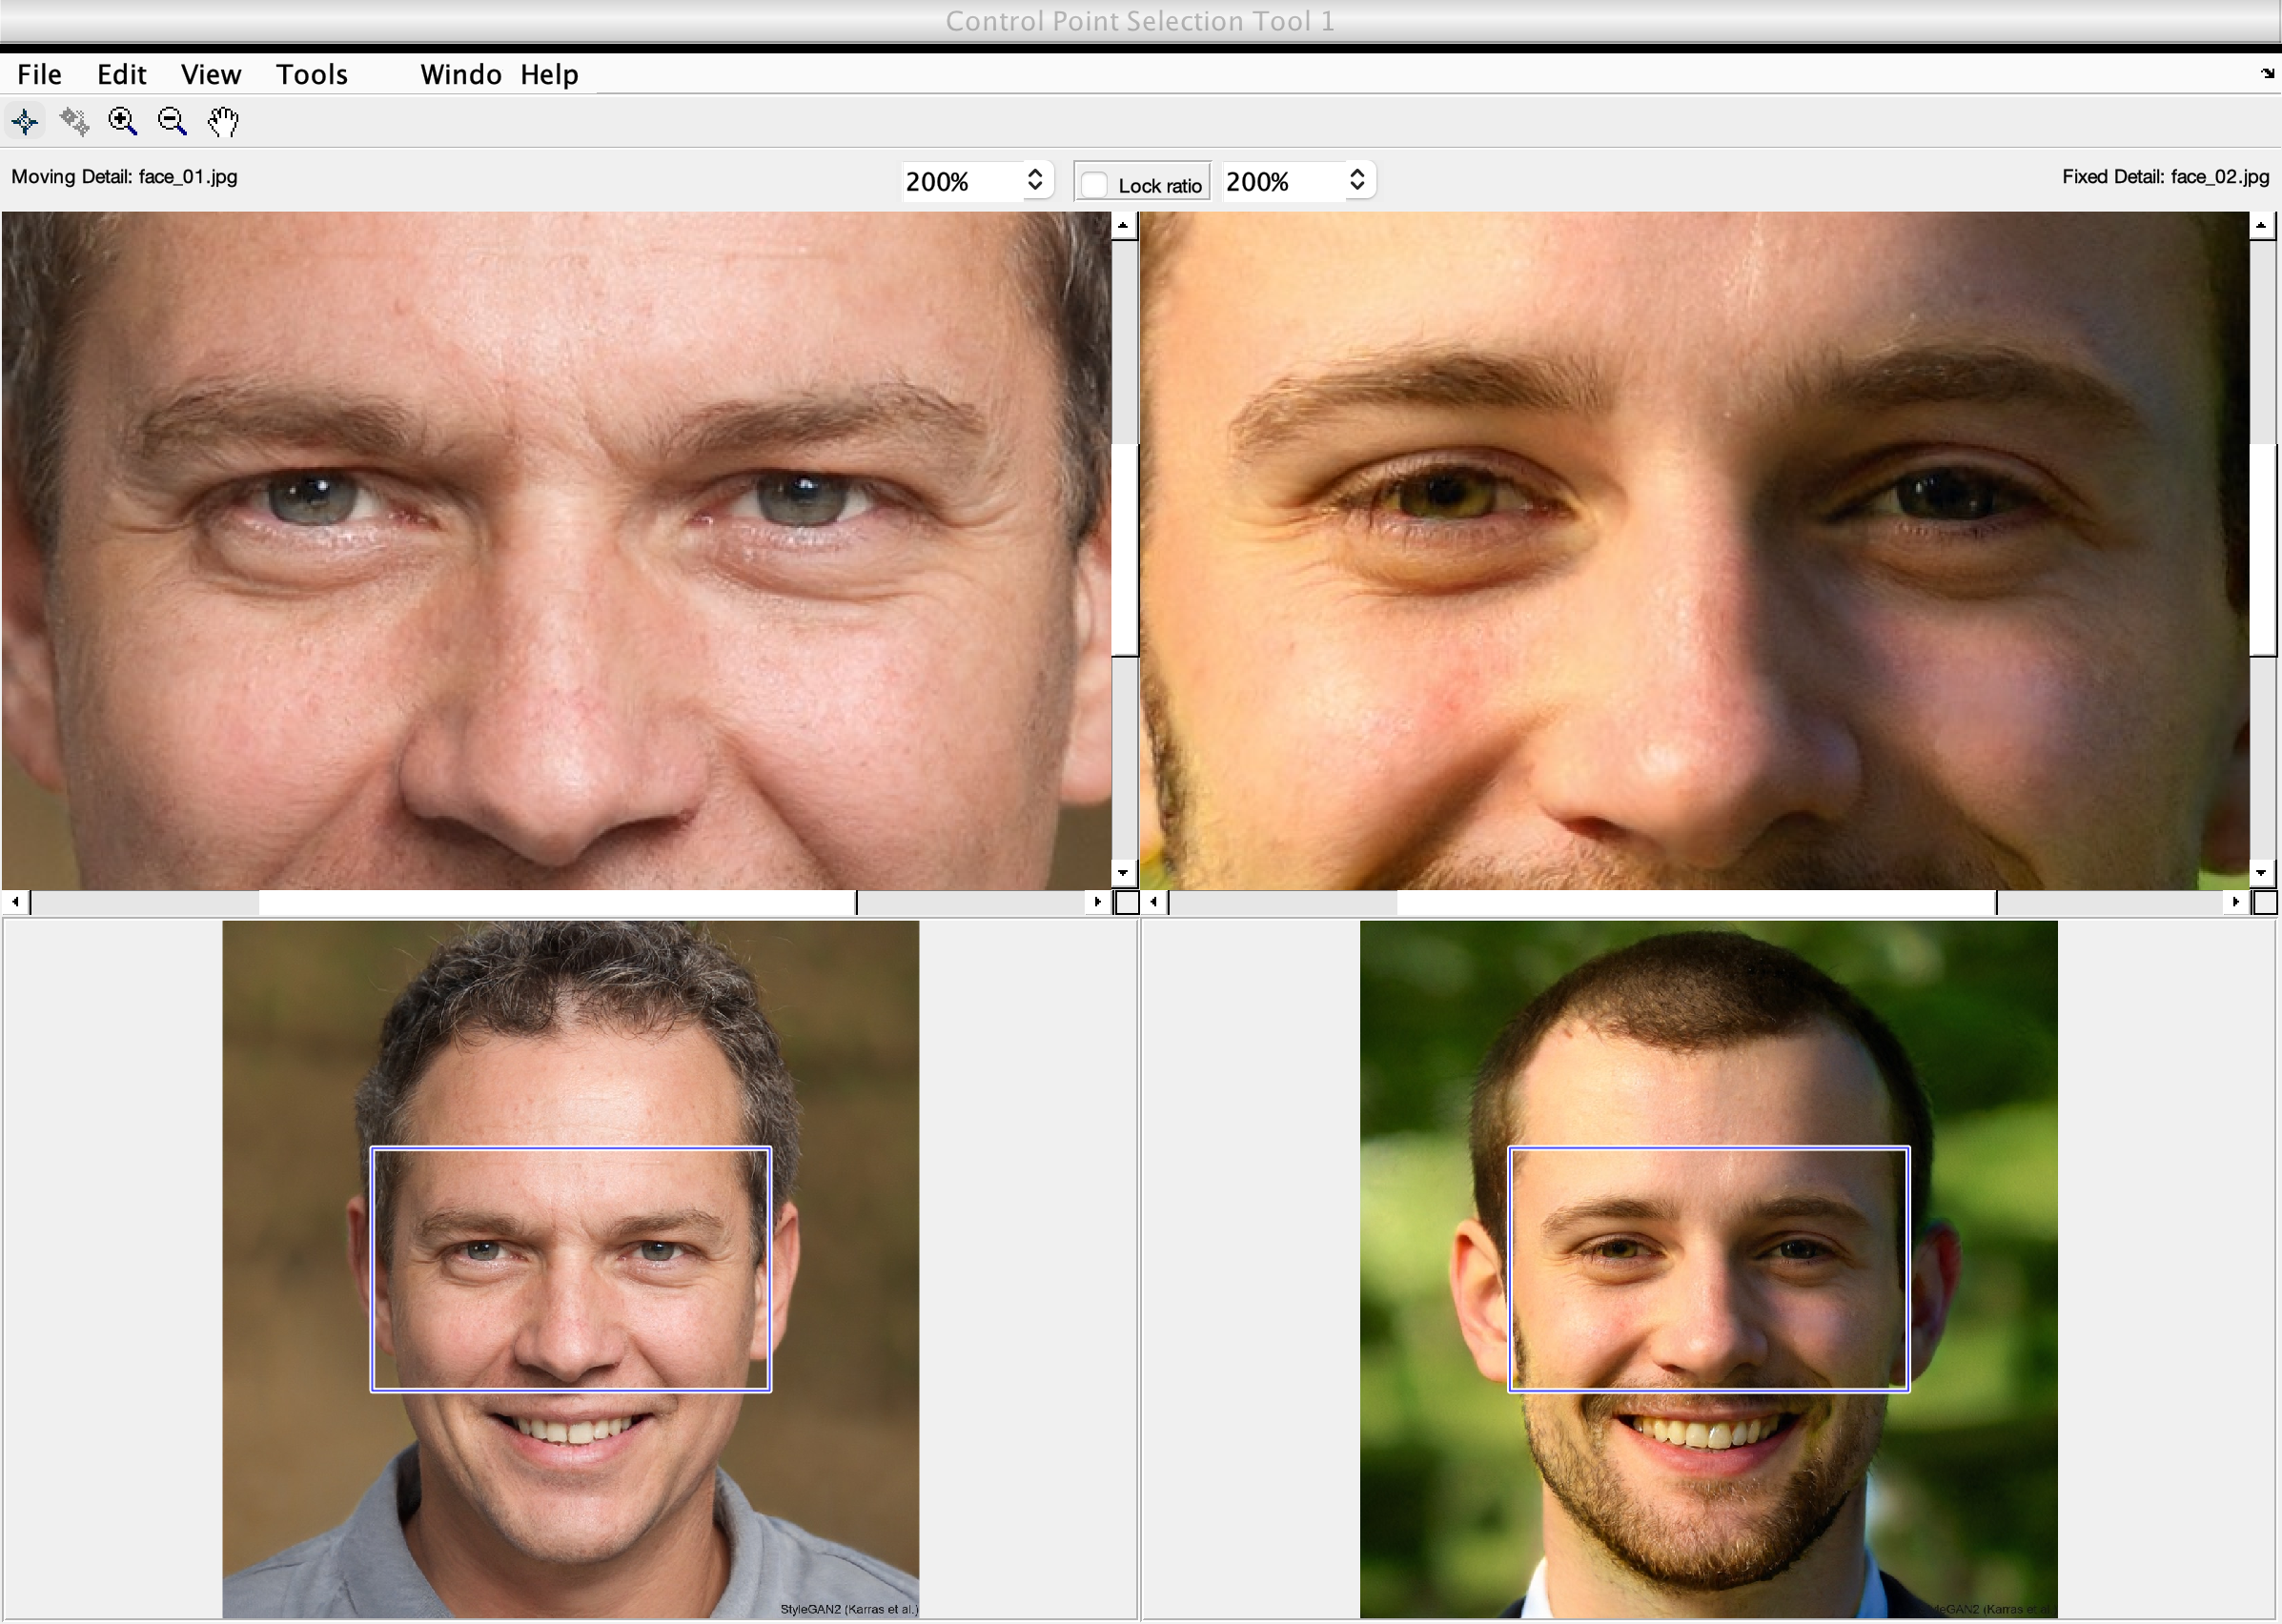

% Bedienung des Control Point Selection Tools
    % Mit "Tools" > "Add Points", Punkte auswählen (abwechselnd linkes und
    % rechtes Bild). Mit Export Points to Workspace die Punkte exportieren.
    % Namen für die Variablen: source_points und target_points
    % Siehe auch: https://www.youtube.com/watch?v=7bFF0JYM8E4

cpselect("face_01.jpg","face_02.jpg")

## Punkte speichern

Variablennamen aus Workspace als zweites Argument angeben. Die Variablennamen sollten mit "source_points" und "target_points" benannt sein um später im Morphingprogramm verwendet werden zu können.

save("points/source_points_face_01_62.mat","source_points");
save("points/target_points_face_02_62.mat","target_points");

## Bestehende Punkte bearbeiten

load("source_points_face_01_62.mat")
load("target_points_face_02_62.mat")

cpselect("face_01.jpg","face_02.jpg",source_points,target_points)

## Punkte laden

Z.B. um den Inhalt zu betrachten oder bestehende Punkte mit MATLAB Befehlen im Command Window zu bearbeiten.

load("source_points_trivial.mat");
load("target_points_trivial.mat");